# **Iniciação Científica**

#### Tema: Análise de Eficiência de Desacopladores e Técnicas de Projeto de Controladores PI SISO para Processos de Moagem

**Voluntária IC:** Grazielle Amanda do Carmo Café

**Orientador:** Dr. Márcio Braga

close all
clearvars

**01. Processo de Moagem descrito por Reis (2018)**

s = tf('s', 'TimeUnit', 'seconds');
G(1,1) = ((0.032)/((2.307*s+1)*(2.307*s+1)));
Ga(1,1) = exp(-3*s);
ganhoG11 = 0.032; 

num_G11 = (0.032);
den_G11 = 5.322*s^2 + 4.614*s + 1;

G(1,2) = ((-0.467)/(25.385*s+1));
Ga(1,2) = exp(-3*s);

G(1,3) = ((-0.041)/((41.011*s+1)*(5.143*s+1)));
Ga(1,3) = exp(-6*s);

G(1,4) = ((0.172)/(39.231*s+1));
Ga(1,4) = exp(-3*s);


G(2,1) = ((-0.089)/(27.692*s+1));
Ga(2,1) = exp(-9*s);

G(2,2) = ((-0.003)/(4.615*s+1));
Ga(2,2) = exp(-95*s);
ganhoG22 = -0.003; 

G(2,3) = ((-0.038)/((28.049*s+1)*(1.951*s+1)));
Ga(2,3) = exp(-3*s);

G(2,4) = ((0.927)/(23.077*s+1));
Ga(2,4) = exp(-3*s);



G(3,1) = ((0.018)/((33.058*s+1)*(8.48*s+1)));
Ga(3,1) = exp(-3*s);

G(3,2) = ((0.156)/(36.923*s+1));
Ga(3,2) = exp(-15*s);

G(3,3) = ((-0.017)/((32.354*s+1)*(9.185*s+1)));
Ga(3,3) = exp(-15*s);
ganhoG33 = -0.017; 

G(3,4) = ((0.156)/(27.692*s+1));
Ga(3,4) = exp(-3*s);



G(4,1) = ((1.935)/((142.76*s+1)*(51.083*s+1)));
Ga(4,1) = exp(-3*s);

G(4,2) = ((0.044)/((128.918*s+1)*(39.543*s+1)));
Ga(4,2) = exp(-54*s);

G(4,3) = ((0.396)/((132.864*s+1)*(56.367*s+1)));
Ga(4,3) = exp(-3*s);

G(4,4) = ((-1.265)/((127.877*s+1)*(61.354*s+1)));
Ga(4,4) = exp(-15*s);
ganhoG44 = -1.265; 

G;
Gdelay = Ga;
Gmodel = G.*Gdelay;


**02. Desacoplador estático**

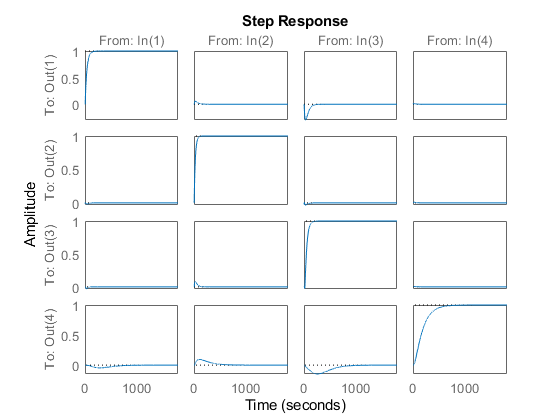

Gstatic = evalfr(Gmodel,0);
Dstatic = inv(Gstatic);
out = Gmodel*Dstatic;
step(out);


% Análise dos índices de desempenho 
% [pv, t] = step(out)
% 
% sp = zeros(size(t,1),1);
% erro = sp - pv; 
% indice.IAE = trapz(abs(erro))
% indice.ITAE = trapz(t.*abs(erro))
% indice.ISE = trapz(erro.^2)

### Etapa 2 - Projeto de Controladores

**Técnica de Sintonia IMC**

% Controlador 1 a partir de G(1,1)
k_1 = 1;
theta_1 = 3; 
tau1_1 = 2.307;
tau2_1 = 2.307;
tau_c1 = theta_1; 

kp_1 = (tau1_1 + tau2_1)/(k_1 * (tau_c1 + theta_1));
% kp_1 = 0.1;
ti_1 = (tau1_1 + tau2_1);
ki_1 = kp_1 / ti_1;

td_1 = (tau1_1 * tau2_1) / (tau1_1 + tau2_1);
kd_1 = kp_1 * td_1;

C1 = pid(kp_1, ki_1, kd_1)

C1 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.769, Ki = 0.167, Kd = 0.887
 
Continuous-time PID controller in parallel form.




% Controlador 2 a partir de G(2,2)
k_2 = 1;
theta_2 = 95; 
tau_2 = 4.615;
tau_c2 = theta_2; 

kp_2 = (2*tau_2 + theta_2)/(k_2 * (2*tau_c2 + theta_2))

kp_2 = 0.3657


ti_2 = tau_2 + (theta_2 / 2);
ki_2 = kp_2 / ti_2;

td_2 = (tau_2 * theta_2)/(2*tau_c2 + theta_2)

td_2 = 1.5383

kd_2 = kp_2 * td_2;

C2 = pid(kp_2, ki_2, kd_2)

C2 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.366, Ki = 0.00702, Kd = 0.563
 
Continuous-time PID controller in parallel form.




% Controlador 3 a partir de G(3,3)
k_3 = 1;
theta_3 = 15; 
tau1_3 = 32.3545;
tau2_3 = 9.185;
tau_c3 = theta_3; 

kp_3 = (tau1_3 + tau2_3)/(k_3 * (tau_c3 + theta_3));

ti_3 = (tau1_3 + tau2_3);
ki_3 = kp_3 / ti_3;

td_3 = (tau1_3 * tau2_3) / (tau1_3 + tau2_3);
kd_3 = kp_3 * td_3;

C3 = pid(kp_3, ki_3, kd_3)

C3 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.38, Ki = 0.0333, Kd = 9.91
 
Continuous-time PID controller in parallel form.





% Controlador 4 a partir de G(4,4)
k_4 = 1;
theta_4 = 15; 
tau1_4 = 127.877;
tau2_4 = 61.354;
tau_c4 = theta_4; 

kp_4 = (tau1_4 + tau2_4)/(k_4 * (tau_c4 + theta_4));

ti_4 = (tau1_4 + tau2_4);
ki_4 = kp_4 / ti_4;

td_4 = (tau1_4 * tau2_4) / (tau1_4 + tau2_4);
kd_4 = kp_4 * td_4;

C4 = pid(kp_4, ki_4, kd_4)

C4 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 6.31, Ki = 0.0333, Kd = 262
 
Continuous-time PID controller in parallel form.




%Simulação
% for i = 1:4
%     for j = 1:4
%         spaceGij = ss(Gmodel(i,j))
%     end
% end

spaceG11 = ss(Gmodel(1,1));
spaceG12 = ss(Gmodel(1,2));
spaceG13 = ss(Gmodel(1,3));
spaceG14 = ss(Gmodel(1,4));
spaceG21 = ss(Gmodel(2,1));
spaceG22 = ss(Gmodel(2,2));
spaceG23 = ss(Gmodel(2,3));
spaceG24 = ss(Gmodel(2,4));
spaceG31 = ss(Gmodel(3,1));
spaceG32 = ss(Gmodel(3,2));
spaceG33 = ss(Gmodel(3,3));
spaceG34 = ss(Gmodel(3,4));
spaceG41 = ss(Gmodel(4,1));
spaceG42 = ss(Gmodel(4,2));
spaceG43 = ss(Gmodel(4,3));
spaceG44 = ss(Gmodel(4,4));


Did = eye(4,4);

SimOut = sim('reis_simulink.slx')

SimOut = 	1.0e+03 *

         0
    0.0010
    0.0010
    0.0010
    0.0018
    0.0026
    0.0037
    0.0050
    0.0065
    0.0082
